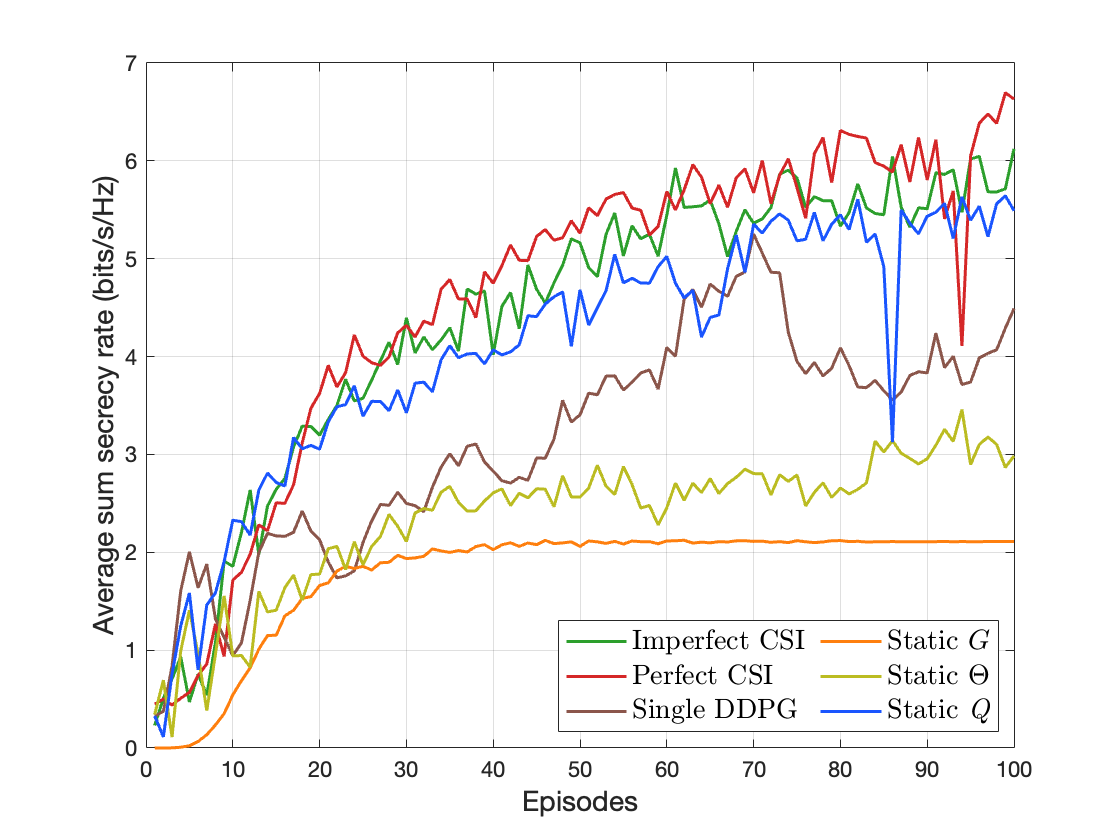

colors = ...
 1/256*[ 31,119,180; % 1 默认蓝色
        255,127,14;  % 2 橘色
         44,160,44;  % 3 绿色
        214,39,40;   % 4 红色
        148,103,189; % 5 紫色
        140,86,75;   % 6 棕色 
       227,119,194;  % 7 粉色
       127,127,127;  % 8 灰色
       188,189,34;   % 9 青棕
       23,190,207;   % 10 淡蓝
       26,85,255;    % 11 鲜蓝色
       ];
plot(1:100,rate_robust_ep,'Color', [colors(3,:)],'LineWidth', 1.5)
hold on
plot(1:100,rate_trajectory_ep,'Color', [colors(4,:)],'LineWidth', 1.5)

plot(1:100,rate_single_ep,'Color', [colors(6,:)],'LineWidth', 1.5)
plot(1:100,rate_G_ep,'Color', [colors(2,:)],'LineWidth', 1.5)
plot(1:100,rate_theta_ep,'Color', [colors(9,:)],'LineWidth', 1.5)
plot(1:100,rate_pro_ep,'Color', [colors(11,:)],'LineWidth', 1.5)

legend( ...
    'Imperfect CSI', ...
    'Perfect CSI', ...
    'Single DDPG',...
    'Static $G$',...
    'Static $\Theta$',...  
    'Static ${\bf \textit Q}$',...
    'interpreter','latex',...
    'Location','southeast', ...
    'NumColumns',2,...
    'FontSize',14);
ylim([0 7]);
xlabel('Episodes','FontSize',14);
ylabel('Average sum secrecy rate (bits/s/Hz)','FontSize',14);
grid on